t=linspace(0,100,1e3);

u_lim = 1;
phi_lim = 0.2;
omega_lim = 0.2;

a=5

a = 5

b=1

b = 1

scaler=5

scaler = 5


scaler=scaler*0.5;
da=a/scaler

da = 2

db=b/scaler

db = 0.4000

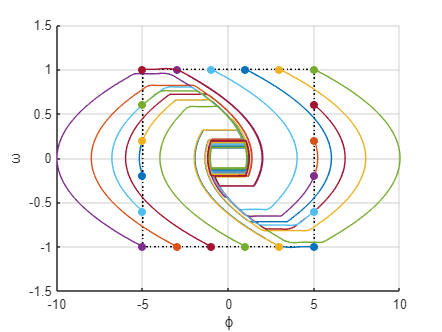


P=[-a b];
dP=[da 0
    0 -db
    -da 0
    0 db
    ];

close all
figure
hold on

for i=1:4
    for j=1:scaler*2
        P=[P;P(end,:)+dP(i,:)];
    end
end
grid on

plot(P(:,1),P(:,2),':k')

for p=P'
    x0=flip(p');
    [~,y]=ode45(@(t,x) next(x,u_lim,phi_lim, omega_lim),t,x0);
    plt=plot(y(:,2),y(:,1));
    scatter(x0(2),x0(1),"filled","MarkerFaceColor",plt.Color)
end

xlabel("\phi")
ylabel("\omega")

function y=next(x, u_lim, phi_lim, omega_lim)

% X=[omega; phi]
% Y=[dOmega/dt; dPhi/dt]

M=-10;
J=100;

w = x(1);
phi = x(2);

if abs(w) < omega_lim
    w=0;
end

if abs(phi) < phi_lim
    phi=0;
end

u = phi - sign(w)* ( J * w^2 )/(2*M);
dw = (M/J)*sign(u);
if abs(u) < u_lim
    dw=0;
end

y=[dw; x(1)];
end
